%testNN = NeuralNet(2, [2, 2])


input = readmatrix('inputStep1.csv')

input =     1.0000         0
    1.0000         0
    1.0000    0.0005
    1.0000    0.0019
    1.0000    0.0041
    1.0000    0.0069
    1.0000    0.0104
    1.0000    0.0145
    1.0000    0.0189
    1.0000    0.0237


output = readmatrix('outputStep1.csv')

output =          0
    0.0005
    0.0019
    0.0041
    0.0069
    0.0104
    0.0145
    0.0189
    0.0237
    0.0288


input = input'

input =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
         0         0    0.0005    0.0019    0.0041    0.0069    0.0104    0.0145    0.0189    0.0237    0.0288    0.0340    0.0394    0.0449    0.0503    0.0557    0.0610    0.0662    0.0712    0.0760    0.0806    0.0849    0.0890    0.0928    0.0963    0.0994    0.1023    0.1049    0.1072    0.1092    0.1110    0.1124    0.1136    0.1146    0.1153    0.1158    0.1162    0.1163    0.1163    0.1161    0.1158    0.1153    0.1148    0.1141    0.1134    0.1127    0.1118    0.1110    0.1101 

output = output'

output =          0    0.0005    0.0019    0.0041    0.0069    0.0104    0.0145    0.0189    0.0237    0.0288    0.0340    0.0394    0.0449    0.0503    0.0557    0.0610    0.0662    0.0712    0.0760    0.0806    0.0849    0.0890    0.0928    0.0963    0.0994    0.1023    0.1049    0.1072    0.1092    0.1110    0.1124    0.1136    0.1146    0.1153    0.1158    0.1162    0.1163    0.1163    0.1161    0.1158    0.1153    0.1148    0.1141    0.1134    0.1127    0.1118    0.1110    0.1101    0.1092    0.1083


size(input)

ans =      2   100


size(output)

ans =      1   100


net = feedforwardnet([10, 10, 10])

net =

    Neural Network
 
              name: 'Feed-Forward Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 4
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 230
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1; 1; 1]
      in


%net.trainParam.epochs = 30
[net,tr] = train(net,input,output)

net =

    Neural Network
 
              name: 'Feed-Forward Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 4
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 251
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1; 1; 1]
      in

tr = struct with fields:
        trainFcn: 'trainlm'
      trainParam: [1×1 struct]
      performFcn: 'mse'
    performParam: [1×1 struct]
        derivFcn: 'defaultderiv'
       divideFcn: 'dividerand'
      divideMode: 'sample'
     divideParam: [1×1 struct]
        trainInd: [1 5 6 7 8 11 12 13 14 16 17 18 19 21 22 24 26 27 28 29 30 31 32 33 35 39 41 45 46 47 48 50 51 52 53 55 56 57 58 60 61 63 64 65 67 68 69 70 72 74 75 76 79 80 81 82 83 84 85 86 88 89 91 92 93 95 96 98 99 100]
          valInd: [3 9 10 15 23 25 36 38 40 59 66 73 77 78 97]
         testInd: [2 4 20 34 37 42 43 44 49 54 62 71 87 90 94]
            stop: 'Validation stop.'
      num_epochs: 10
       trainMask: {[1×100 double]}
         valMask: {[1×100 double]}
        testMask: {[1×100 double]}
      best_epoch: 4
            goal: 0
          states: {'epoch'  'time'  'perf'  'vperf'  'tperf'  'mu'  'gradient'  'val_fail'}
           epoch: [0 1 2 3 4 5 6 7 8 9 10]
            time: [7.4582 7.4764 7.4821 7.4899 7.

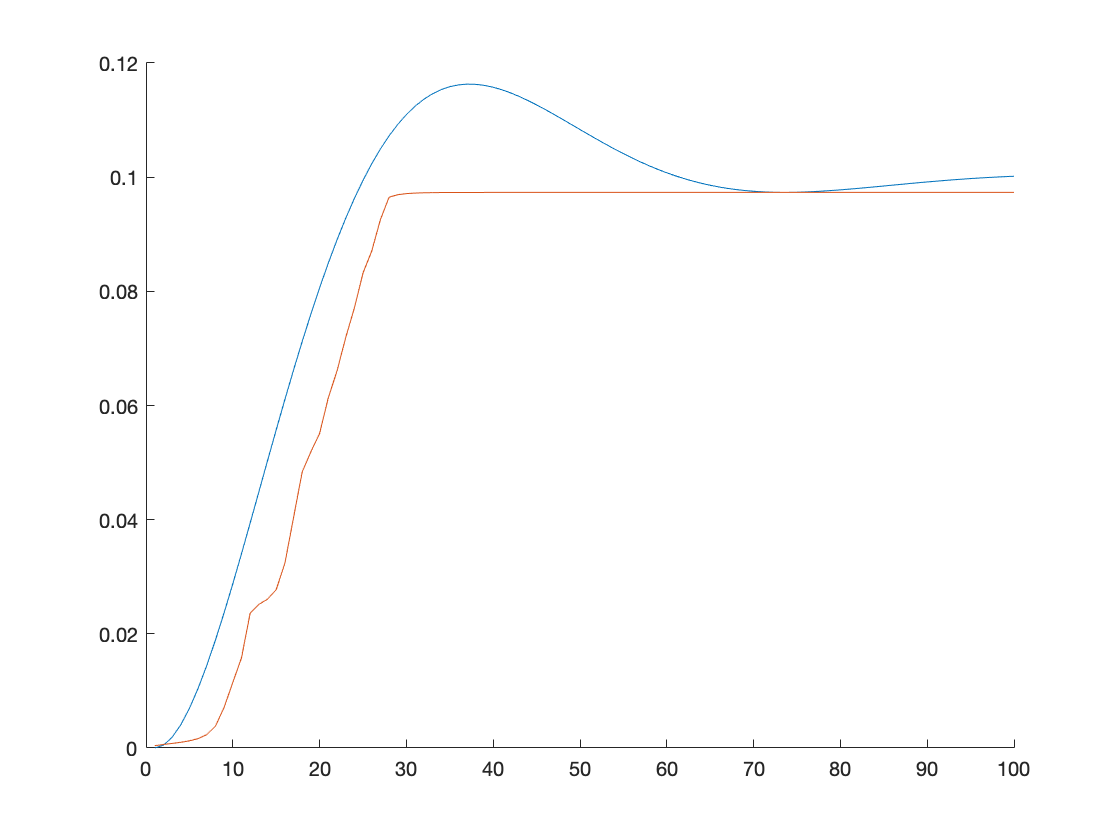



%Visualization
figure
hold on
plot(1:1:100, output)
test = [1:1:100];
for i = 1:100
    if i == 1
        test(i) = net(input(:,i));
    else
        test(i) = net([input(1,i); test(i-1)]);
    end
end
plot(1:1:100, test)